% green = "images/green_cubes_Color.png";

green = "images/25_Color.png"

green = "images/25_Color.png"

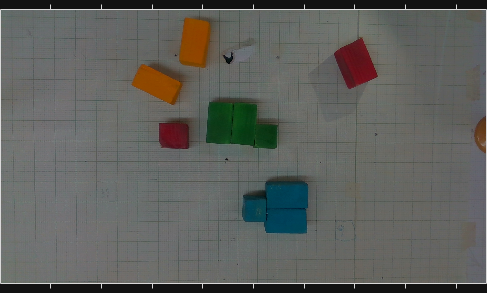


[I_g, g_map] = imread(green); % TODO: Adaptive hist equalization
imshow(I_g)

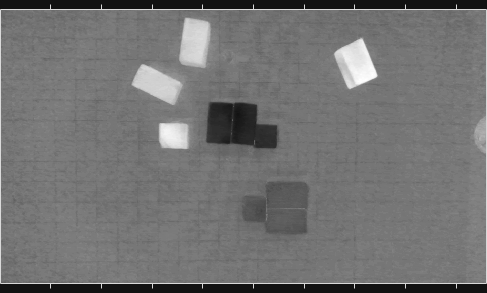

[rg,gg,bg] = imsplit(I_g);
imgLab = rgb2lab(I_g);
[L,a,b] = imsplit(imgLab);
imshow(a,[])

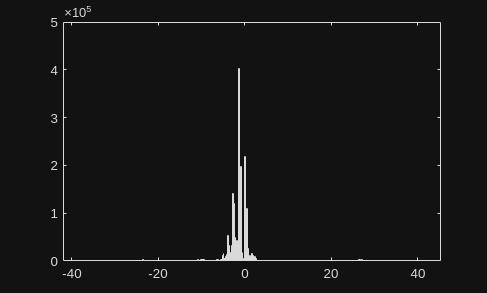

histogram(a)

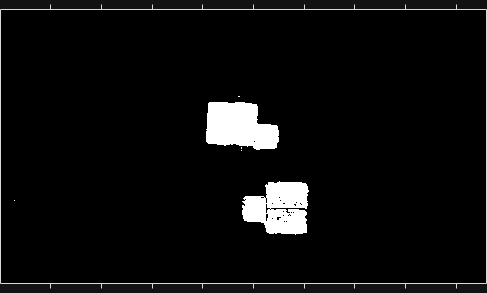


masked = a < -8;
imshow(masked);

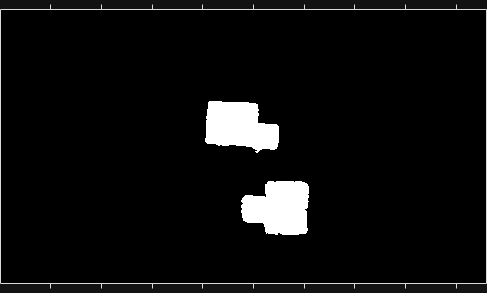

% Segmentation stage

masked_med = wiener2(masked, [5,5]);
mask1 = bwareaopen(masked_med, 2000);
mask2 = imclearborder(mask1);
mask3 = imfill(mask2, "holes");
mask4 = imdilate(mask3, 1);
imshow(mask4)


% gmask = imbinarize(g)
% imshow(gmask)

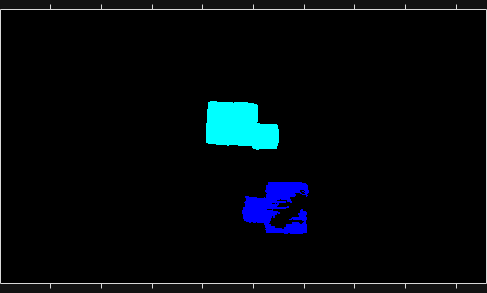

% 

boxCC = bwconncomp(mask4);
boxLabel = labelmatrix(boxCC);
boxRGB = label2rgb(boxLabel, "jet", "k", "shuffle");
imshow(boxRGB);

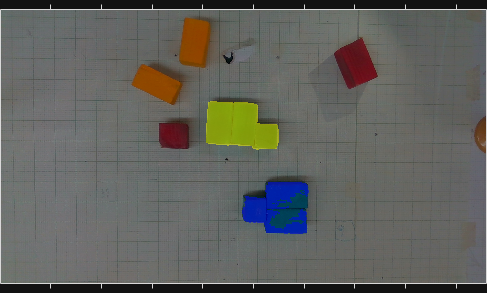


overlay = labeloverlay(I_g, boxLabel, 'Transparency', 0.5);
imshow(overlay)

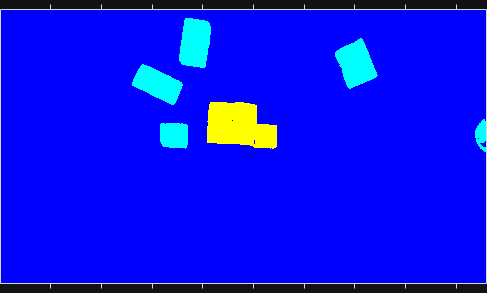

clusters = segment_cluster(I_g, 3);
imshow(label2rgb(clusters))

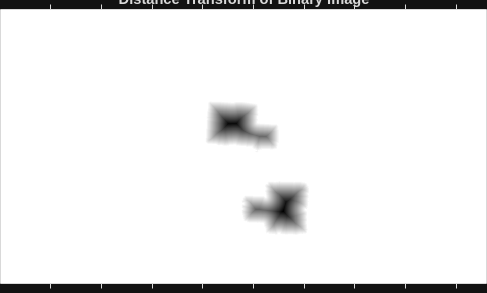

grayscale = im2gray(I_g);
Icomp = imcomplement(grayscale);


D = -bwdist(~mask4);
imshow(D,[])
title('Distance Transform of Binary Image')

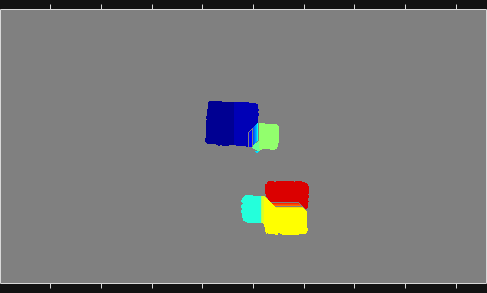


L = watershed(D);
L(~mask4) = 0;
rgb = label2rgb(L,'jet',[.5 .5 .5]);
imshow(rgb, []);